% Parámetros del sistema
bit_rate = 100e3;          % Transmission rate = 100 Kbps
sample_rate = 200e3;       % Sample rate = 200 kHz
samples_per_bit = 2;       % Sample rate de 2 samples/bit


M = 24717;                % Largo de un frame en bits
num_frames = 122;         % Número de frames a enviar
preamble = repmat([1 0], 1, 12);  % Preambulo de 24 bits (101010...)

% Generar datos aleatorios para los frames
data_bits = round(rand(1, M * num_frames));  % Genera los bits aleatorios

packet = [preamble,data_bits];

% Inicializar la señal transmitida
tx_signal = [];

% Añadir el preámbulo a cada frame y codificar Manchester
for i = 1:num_frames
    frame_bits = data_bits((i-1)*M + 1 : i*M); % Obtener un frame
    frame_with_preamble = [preamble, frame_bits];  % Añadir preámbulo al frame
    manchester_frame = manchester_encoding(frame_with_preamble, samples_per_bit);
    tx_signal = [tx_signal, manchester_frame];  % Añadir a la señal total
end

sig_inicial_sync = ones(1,100000)*1;

tx_signal_gnu = [sig_inicial_sync, tx_signal];


% Función de codificación Manchester
function manchester_signal = manchester_encoding(bits, samples_per_bit)
    % Codificación Manchester de un arreglo de bits (señal cuadrada entre -1 y 1)
    manchester_signal = [];
    
    for i = 1:length(bits)
        if bits(i) == 0
            manchester_bit = [1 -1];  % Codificación para 0
        else
            manchester_bit = [-1 1];  % Codificación para 1
        end
        manchester_signal = [manchester_signal, manchester_bit];  % Añadir el bit codificado
    end
    
    % Repetir la señal para que tenga el número correcto de samples por bit
    manchester_signal = repelem(manchester_signal, samples_per_bit / 2);
end



% Canal con ruido Gaussiano
rx_signal = tx_signal + 0.1 * randn(size(tx_signal));  % Añadir ruido gaussiano

% Decodificación Manchester
decoded_bits = manchester_decoding(rx_signal, samples_per_bit, length(preamble));

% Función de decodificación Manchester
function decoded_bits = manchester_decoding(signal, samples_per_bit, preamble_len)
    % Decodificación Manchester de la señal recibida
    num_bits = length(signal) / samples_per_bit;
    decoded_bits = zeros(1, num_bits);
    
    for i = 1:num_bits
        sample = signal((i-1)*samples_per_bit + 1 : i*samples_per_bit);
        % Decodificación basada en el promedio de las muestras
        if mean(sample(1:samples_per_bit/2)) > 0
            decoded_bits(i) = 0;
        else
            decoded_bits(i) = 1;
        end
    end
    
    % Eliminar preámbulo
    %decoded_bits = decoded_bits(preamble_len+1:end);
end

% Calcular BER (comparando los bits transmitidos y recibidos)
received_bits = decoded_bits(1:length(data_bits));

decode_tx = manchester_decoding(tx_signal, samples_per_bit, length(preamble));
decode_rx = manchester_decoding(rx_signal, samples_per_bit, length(preamble));

BER = sum(decode_tx ~= decode_rx) / length(data_bits);
fprintf('BER: %.5f\n', BER);

BER: 0.00000


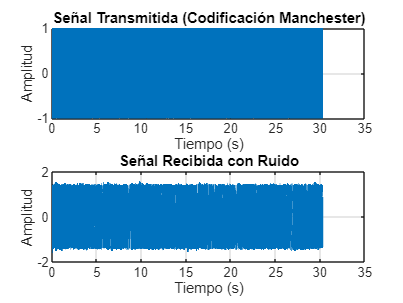

% Gráficas

% Figura 1: Señal transmitida y señal recibida
t = (0:length(tx_signal)-1) / sample_rate;
figure;
subplot(2, 1, 1);
plot(t, tx_signal, 'LineWidth', 1.5);
title('Señal Transmitida (Codificación Manchester)');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

subplot(2, 1, 2);
plot(t, rx_signal, 'LineWidth', 1.5);
title('Señal Recibida con Ruido');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

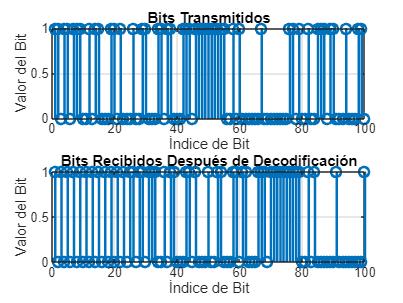


% Figura 2: Bits transmitidos y bits recibidos
figure;
subplot(2, 1, 1);
stem(data_bits(1:100), 'LineWidth', 1.5);
title('Bits Transmitidos');
xlabel('Índice de Bit');
ylabel('Valor del Bit');
grid on;

subplot(2, 1, 2);
stem(received_bits(1:100), 'LineWidth', 1.5);
title('Bits Recibidos Después de Decodificación');
xlabel('Índice de Bit');
ylabel('Valor del Bit');
grid on;

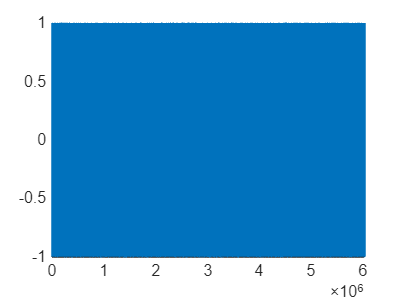

write_float_binary(tx_signal,'envio.bin');

read = read_float_binary('envio.bin')';

figure
plot(read)

%asdf = tuasdas

Datos recibidos

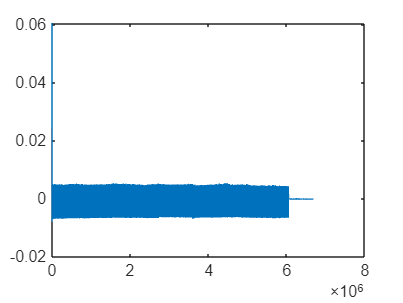

rec = read_float_binary('recepciongnuradio2.bin')';

figure
plot(rec)

Procesamiento

% Parámetros del preámbulo
preamble = repmat([1 -1], 1, 12);  % Codificación Manchester de 101010...

% Señal recibida (rx_signal ya contiene el ruido y la distorsión)
% Preámbulo transmitido codificado en Manchester
rx_signal2 = rec; % (tu señal recibida)

% Realizar la correlación entre el preámbulo y la señal recibida
correlation = xcorr(rx_signal2, preamble);

% Encontrar el punto máximo de la correlación
[~, idx] = max(abs(correlation));

% Ajustar el índice de sincronización para encontrar el inicio de los datos
sync_point = idx - length(preamble) + 1;

% Extraer la señal sincronizada
synced_signal = rx_signal(sync_point:end);



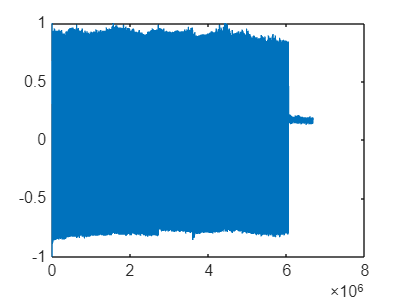

rec_copy = rec(rec <= 0.01);
%rec_copy = rec_copy(rec >= 0.003);

rec_copy = rec_copy(1:length(tx_signal));

% Encuentra el valor mínimo y máximo del vector
min_val = min(rec_copy);
max_val = max(rec_copy);

% Aplica la normalización Min-Max
rec_copy_norm = 2*((rec_copy - min_val) / (max_val - min_val))-1;


figure
plot(rec_copy_norm)

bits_gnuradio = manchester_decoding(rec_copy_norm, samples_per_bit, length(preamble));

Error using zeros
Size inputs must be integers.

Error in MANCHESTERUNITED>manchester_decoding (line 61)
    decoded_bits = zeros(1, num_bits);

disp(bits_gnuradio(1:10))

figure
plot(bits_gnuradio(1:100))

%a = asdftuhermana

[C,lag] = xcorr(decode_tx,bits_gnuradio);
C = C/max(C);
figure
plot(C)
%xline(t,"-","Lag: "+t,LabelOrientation="horizontal")

function v = write_float_binary (data, filename)

  %% usage: write_float_binary (data, filename)
  %%
  %%  open filename and write data to it as 32 bit floats
  %%

  m = nargchk (1,2,nargin);
  if (m)
    usage (m);
  end

  f = fopen (filename, 'wb');
  if (f < 0)
    v = 0;
  else
    v = fwrite (f, data, 'float');
    fclose (f);
  end
end


function v = read_float_binary (filename, count)

  %% usage: read_float_binary (filename, [count])
  %%
  %%  open filename and return the contents, treating them as
  %%  32 bit floats
  %%

  m = nargchk (1,2,nargin);
  if (m)
    usage (m);
  end

  if (nargin < 2)
    count = Inf;
  end

  f = fopen (filename, 'rb');
  if (f < 0)
    v = 0;
  else
    v = fread (f, count, 'float');
    fclose (f);
  end
end

